# 演習5_2　ラグランジュ補間関数

- 分点データ1を通る補間関数をラグランジュ補間関数のMATLABプログラムで計算しグラフを作成しなさい. 

- できたら分点データ2に対して同じように計算しグラフを作成しなさい.

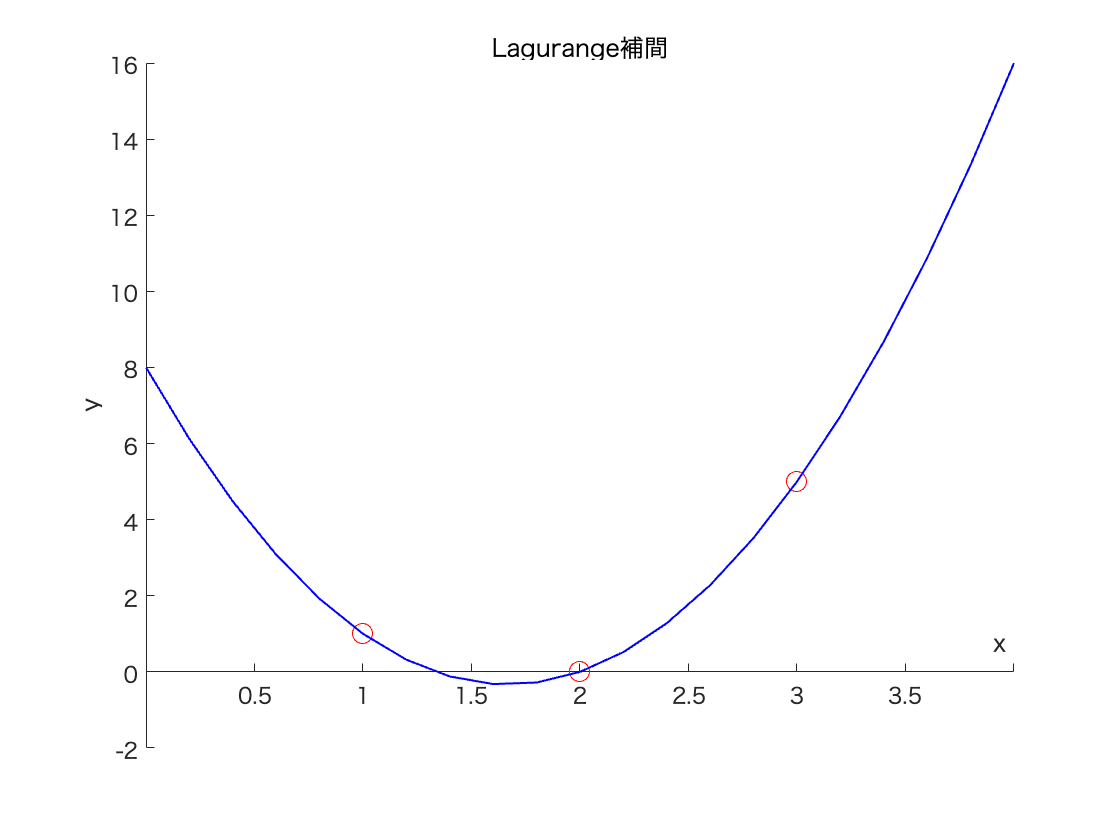

% リスト5-2
% 分点データ1
xd=[1 2 3];
yd=[1 0 5];

% 分点データ2
%xd=[0.5 1 2 3];
%yd=[1 1 0 5];

% lagrunge近似関数による補間計算
% xの定義
x=0:0.2:4;
% xの列数
num=size(x,2);
% yの計算
y=zeros(1,num);
for i=1:num
 y(i)=lagrange(xd,yd,x(i));
end
clf;
hold on;
% 分点（色：赤〇，マーカサイズ：10）  
plot(xd,yd,'ro','markersize',10);
% 補間点（色：青，線太さ：1）  
plot(x,y,'b','linewidth',1);
xlabel('x');    % x軸ラベル
ylabel('y');    % y軸ラベル
title('Lagurange補間'); 
% x,y軸位置の設定
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
hold off;

# 演習5-3　ルンゲの現象を見る

分点の間で補間多項式が大きく変動する現象，

分点データ1でできたら分点データ2に対して同じように計算しグラフを作成しなさい.

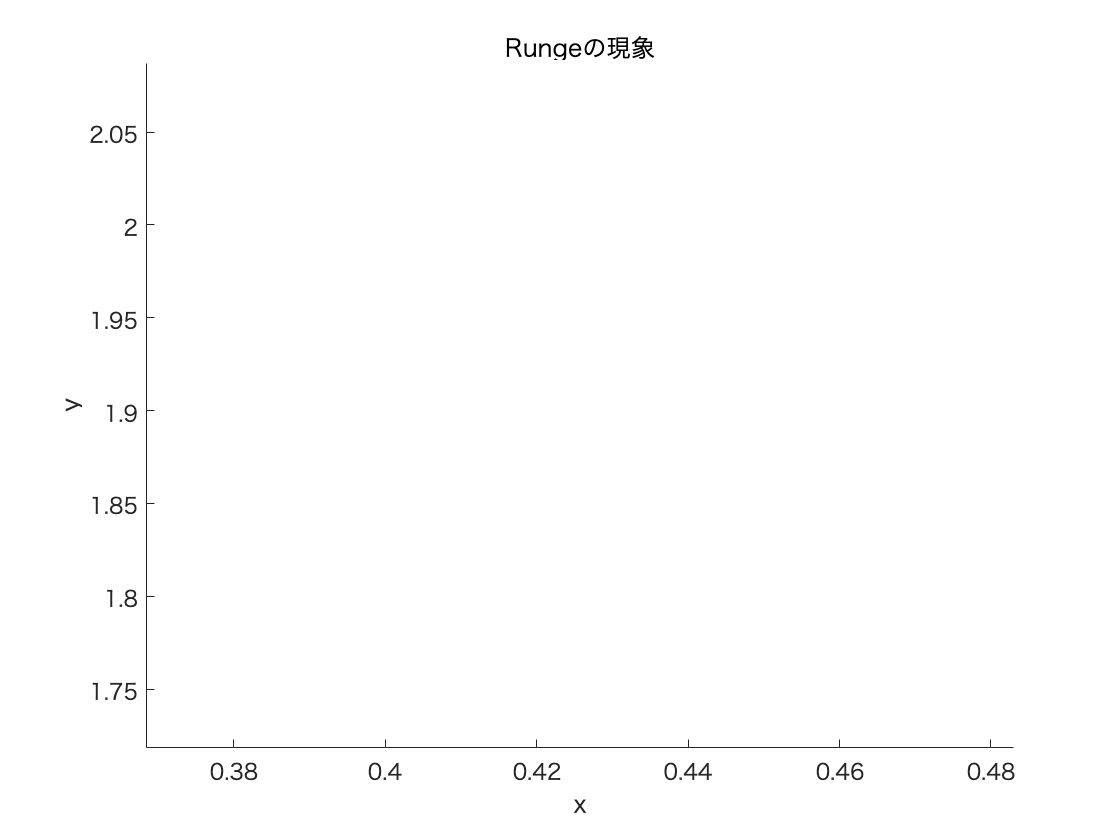

% xd : 分点データ
% ケース1　分点を11点使用
%xd=linspace(-1,1,11);

% ケース2　分点を15点使用
xd=linspace(-1,1,15);
% 
num=size(xd,2);
% yd : 分点での関数値計算
% 明示的に ydの配列宣言が必要
yd=zeros(1,num);
for i=1:num
 yd(i)=1/(25*xd(i)^2 + 1);
end
% lagrange補間関数(リスト6-2a)を使った補間点データの計算
% x : データ点
% y : データ点でのlagrange補間出力
x=-1:0.02:1;
y=zeros(size(x,1),size(x,2));
num=size(x,2);
for i=1:num
 y(i)=lagrange(xd,yd,x(i));
end

% リスト6-2c
% グラフ出力 
clf;
hold on;
% 分点（色：赤，マーカ：・，大きさ：10）                 
plot(xd,yd,'ro','markersize',10);
% 補間点（色：青，線太さ：3）  
plot(x,y,'b','linewidth',1);
title('Rungeの現象');
% x軸，y軸のラベル
xlabel('x'), ylabel('y');  
% x軸，y軸の範囲設定
axis([-1 1 -1 2]);


hold off;

# 演習5_4　ルンゲの現象の改善

チェビシェフ分点でRungeの現象を改善できる

分点データ1でできたら分点データ2に対して同じように計算しグラフを作成しなさい.

% チェビシェフ分点数
num=15;
% チェビシェフ分点xd(i)と関数値yd(i)の計算
xd=zeros(1,num);
yd=zeros(1,num);
for i=1:num
  xd(i)=cos(pi/num*(i-0.5));
  yd(i)=1/(25*xd(i)^2 + 1);
end


% lagrange補間関数を使った補間点データの計算
% x : データ点
% y : データ点でのlagrange補間出力
x=-1:0.02:1;
y=zeros(size(x,1),size(x,2));
num=size(x,2);
for i=1:num
 y(i)=lagrange(xd,yd,x(i));
end

% リスト6-2c
% グラフ出力 
clf;
hold on;
% 分点（色：赤，マーカ：・，大きさ：10）                 
plot(xd,yd,'ro','markersize',10);
% 補間点（色：青，線太さ：3）  
plot(x,y,'b','linewidth',1);
title('Rungeの現象の改善');
% x軸，y軸のラベル
xlabel('x'), ylabel('y');  
% x軸，y軸の範囲設定
axis([-1 1 -1 2]);

hold off;

ラグランジュ関数　（ファイルの最後に関数定義を記述する）

function p=lagrange(xd,yd,x)
 n=size(xd,2);
 phi=zeros(1,n);
 p = 0;
 for i = 1:n
  phi(i) = 1;
  for j = 1:n
   if i ~= j
%   1行穴埋め
%   phi(i) = phi(i)* .....???
    phi(i) = phi(i)*(x-xd(j))/(xd(i) - xd(j));
   end
  end
  p = p + yd(i)*phi(i);
 end
end
